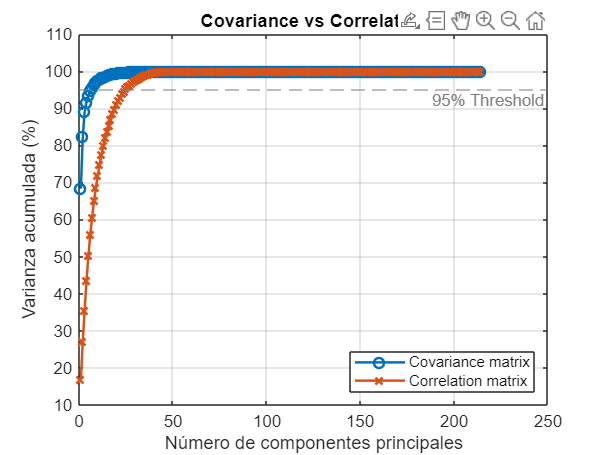

clear all
close all

% Cargar datos
DATA = xlsread('Five_times_Kinematics_HT_Query_final.xlsx');

MF = DATA(:,2);
X_lin = DATA(:,5:end)';  % Trasponer para que filas sean variables

% Crear kernel cuadrático
X = X_lin;
lin_dim = size(X,1);
for i = 1:lin_dim
    X(lin_dim+i, :) = X(i, :).^2;
end

quad_dim = size(X,1);
for i = 1:lin_dim
    if mod(i,5) == 0
        i = i + 1;
    end
    if i < lin_dim  % Evitar error de índice fuera de rango
        X(quad_dim+i, :) = X(i,:) .* X(i+1,:);
    end
end

% Eliminar filas cero
rowsToKeep = [];
for i = 1:size(X,1)
    if sum(abs(X(i,:))) ~= 0
        rowsToKeep = [rowsToKeep; i];
    end
end
X = X(rowsToKeep, :);

% Quitar última fila si es necesario
X_dim = size(X,1);
X(X_dim,:) = [];

% PCA usando correlation matrix
S_corr = corrcoef(X');

% PCA usando covariance matrix
S_cov = cov(X');

% Eigenvalues correlation
[Vcorr, Dcorr] = eig(S_corr);
eigenvalues_correlation = sort(diag(Dcorr), 'descend');

% Eigenvalues covariance
[Vcov, Dcov] = eig(S_cov);
eigenvalues_covariance = sort(diag(Dcov), 'descend');

% Normalizar
eigenvalues_correlation = eigenvalues_correlation / sum(eigenvalues_correlation);
eigenvalues_covariance = eigenvalues_covariance / sum(eigenvalues_covariance);

% Índices
x_corr = 1:length(eigenvalues_correlation);
x_cov = 1:length(eigenvalues_covariance);

% Graficar Scree Plot
figure;
plot(x_cov, cumsum(eigenvalues_covariance)*100, 'o-', 'LineWidth', 1.5);
hold on;
plot(x_corr, cumsum(eigenvalues_correlation)*100, 'x-', 'LineWidth', 1.5);

% Línea 95%
yline(95, '--', '95% Threshold', 'LabelVerticalAlignment', 'bottom', 'Color', [0.5 0.5 0.5]);

% Personalizar
title('Covariance vs Correlation');
xlabel('Número de componentes principales');
ylabel('Varianza acumulada (%)');
grid on;
legend({'Covariance matrix', 'Correlation matrix'}, 'Location', 'southeast');
hold off;